# BIOMECH II HW3 code by Erika Muhlrad

## #1

%a) 

a_0 = [1/sqrt(2); 1/sqrt(2); 0]

a_0 =     0.7071
    0.7071
         0



%b)

a0_inner = a_0 * a_0'

a0_inner =     0.5000    0.5000         0
    0.5000    0.5000         0
         0         0         0



%c)

syms lambda1 lambda2 lambda_f
F = [lambda1 0 0;
    0 lambda2 0;
    0 0 1/(lambda1*lambda2)]

$$F = \left(\begin{array}{ccc} \lambda_{1} & 0 & 0\\ 0 & \lambda_{2} & 0\\ 0 & 0 & \frac{1}{\lambda_{1}\,\lambda_{2}} \end{array}\right)$$


%d)


lambda_f = norm(F*a_0)

$$lambda\_f = \sqrt{\frac{{\left|\lambda_{1}\right|}^{2}}{2}+\frac{{\left|\lambda_{2}\right|}^{2}}{2}}$$



a = F*a_0./lambda_f

$$a = \left(\begin{array}{c} \frac{\sqrt{2}\,\lambda_{1}}{2\,\sqrt{\frac{{\left|\lambda_{1}\right|}^{2}}{2}+\frac{{\left|\lambda_{2}\right|}^{2}}{2}}}\\ \frac{\sqrt{2}\,\lambda_{2}}{2\,\sqrt{\frac{{\left|\lambda_{1}\right|}^{2}}{2}+\frac{{\left|\lambda_{2}\right|}^{2}}{2}}}\\ 0 \end{array}\right)$$


%e)
a_inner = a * a'

$$a\_inner = \begin{array}{l} \left(\begin{array}{ccc} \frac{\lambda_{1}\,\bar{\lambda_{1}}}{\sigma_{1}} & \frac{\lambda_{1}\,\bar{\lambda_{2}}}{\sigma_{1}} & 0\\ \frac{\lambda_{2}\,\bar{\lambda_{1}}}{\sigma_{1}} & \frac{\lambda_{2}\,\bar{\lambda_{2}}}{\sigma_{1}} & 0\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(\frac{{\left|\lambda_{1}\right|}^{2}}{2}+\frac{{\left|\lambda_{2}\right|}^{2}}{2}\right) \end{array}$$




%f)
syms I1 I2 I3 I4 I5 c1 c2 c3

W = (c1*(I1-3)) + c2*(exp(c3*((I4-1)^2))-1)

$$W = c_{2}\,\left({\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}}-1\right)+c_{1}\,\left(I_{1}-3\right)$$

W1 = diff(W,I1)

$$W1 = c_{1}$$

W2 = diff(W,I2)

$$W2 = 0$$

W3 = diff(W,I3)

$$W3 = 0$$

W4 = diff(W,I4)

$$W4 = c_{2}\,c_{3}\,{\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}}\,\left(2\,I_{4}-2\right)$$

W5 = diff(W,I5)

$$W5 = 0$$


%g) 

S = 2*((W1 * eye(3))+ (W4 * a * a'))

$$S = \begin{array}{l} \left(\begin{array}{ccc} 2\,c_{1}+\frac{c_{2}\,c_{3}\,\lambda_{1}\,\sigma_{2}\,\bar{\lambda_{1}}\,\left(2\,I_{4}-2\right)}{\sigma_{1}} & \frac{c_{2}\,c_{3}\,\lambda_{1}\,\sigma_{2}\,\bar{\lambda_{2}}\,\left(2\,I_{4}-2\right)}{\sigma_{1}} & 0\\ \frac{c_{2}\,c_{3}\,\lambda_{2}\,\sigma_{2}\,\bar{\lambda_{1}}\,\left(2\,I_{4}-2\right)}{\sigma_{1}} & 2\,c_{1}+\frac{c_{2}\,c_{3}\,\lambda_{2}\,\sigma_{2}\,\bar{\lambda_{2}}\,\left(2\,I_{4}-2\right)}{\sigma_{1}} & 0\\ 0 & 0 & 2\,c_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\left|\lambda_{1}\right|}^{2}}{2}+\frac{{\left|\lambda_{2}\right|}^{2}}{2}\\ \sigma_{2}={\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}} \end{array}$$


T = F*S*F'

$$T = \begin{array}{l} \left(\begin{array}{ccc} \lambda_{1}\,\bar{\lambda_{1}}\,\left(2\,c_{1}+\frac{c_{2}\,c_{3}\,\lambda_{1}\,\sigma_{2}\,\bar{\lambda_{1}}\,\left(2\,I_{4}-2\right)}{\sigma_{1}}\right) & \frac{c_{2}\,c_{3}\,{\lambda_{1}}^{2}\,\sigma_{2}\,{\bar{\lambda_{2}}}^{2}\,\left(2\,I_{4}-2\right)}{\sigma_{1}} & 0\\ \frac{c_{2}\,c_{3}\,{\lambda_{2}}^{2}\,\sigma_{2}\,{\bar{\lambda_{1}}}^{2}\,\left(2\,I_{4}-2\right)}{\sigma_{1}} & \lambda_{2}\,\bar{\lambda_{2}}\,\left(2\,c_{1}+\frac{c_{2}\,c_{3}\,\lambda_{2}\,\sigma_{2}\,\bar{\lambda_{2}}\,\left(2\,I_{4}-2\right)}{\sigma_{1}}\right) & 0\\ 0 & 0 & \frac{2\,c_{1}}{\lambda_{1}\,\lambda_{2}\,\bar{\lambda_{1}}\,\bar{\lambda_{2}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\left|\lambda_{1}\right|}^{2}}{2}+\frac{{\left|\lambda_{2}\right|}^{2}}{2}\\ \sigma_{2}={\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}} \end{array}$$


pnh = T(3,3);
T = T - pnh*eye(3)

$$T = \begin{array}{l} \left(\begin{array}{ccc} \lambda_{1}\,\bar{\lambda_{1}}\,\left(2\,c_{1}+\frac{c_{2}\,c_{3}\,\lambda_{1}\,\sigma_{2}\,\bar{\lambda_{1}}\,\left(2\,I_{4}-2\right)}{\sigma_{1}}\right)-\sigma_{3} & \frac{c_{2}\,c_{3}\,{\lambda_{1}}^{2}\,\sigma_{2}\,{\bar{\lambda_{2}}}^{2}\,\left(2\,I_{4}-2\right)}{\sigma_{1}} & 0\\ \frac{c_{2}\,c_{3}\,{\lambda_{2}}^{2}\,\sigma_{2}\,{\bar{\lambda_{1}}}^{2}\,\left(2\,I_{4}-2\right)}{\sigma_{1}} & \lambda_{2}\,\bar{\lambda_{2}}\,\left(2\,c_{1}+\frac{c_{2}\,c_{3}\,\lambda_{2}\,\sigma_{2}\,\bar{\lambda_{2}}\,\left(2\,I_{4}-2\right)}{\sigma_{1}}\right)-\sigma_{3} & 0\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\left|\lambda_{1}\right|}^{2}}{2}+\frac{{\left|\lambda_{2}\right|}^{2}}{2}\\ \sigma_{2}={\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}}\\ \sigma_{3}=\frac{2\,c_{1}}{\lambda_{1}\,\lambda_{2}\,\bar{\lambda_{1}}\,\bar{\lambda_{2}}} \end{array}$$

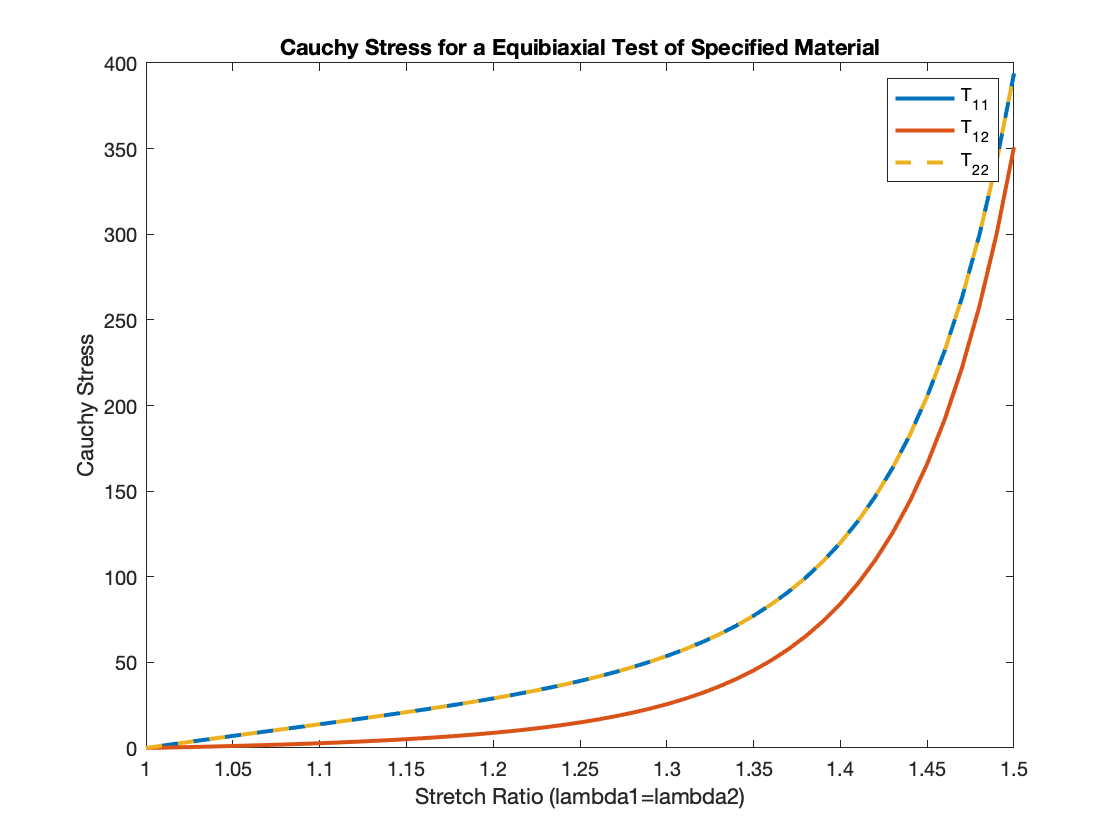


%G(i)


lambda1 = 1:0.01:1.5;
lambda2 = 1:0.01:1.5;

c1 = 10.5;
c2 = 3.2;
c3 = 1.6;

C =  F'*F;

I1 = eval(trace(C));
I4 = eval(lambda_f.^2);

T_11 = subs(T(1,1));
T_12 = subs(T(1,2));
T_22 = subs(T(2,2));

figure(1)
plot(lambda1,T_11,lambda1,T_12,lambda1,T_22, '--', 'linewidth',2)
title(['Cauchy Stress for a Equibiaxial Test ' ...
    'of Specified Material'])
xlabel('Stretch Ratio (lambda1=lambda2)')
ylabel('Cauchy Stress')
legend('T_1_1','T_1_2','T_2_2')


lambda1 = 1:0.01:1.5;
lambda2 = 1;
c1 = 10.5;
c2 = 3.2;
c3 = 1.6;

C =  F'*F

$$C = \left(\begin{array}{ccc} \lambda_{1}\,\bar{\lambda_{1}} & 0 & 0\\ 0 & \lambda_{2}\,\bar{\lambda_{2}} & 0\\ 0 & 0 & \frac{1}{\lambda_{1}\,\lambda_{2}\,\bar{\lambda_{1}}\,\bar{\lambda_{2}}} \end{array}\right)$$

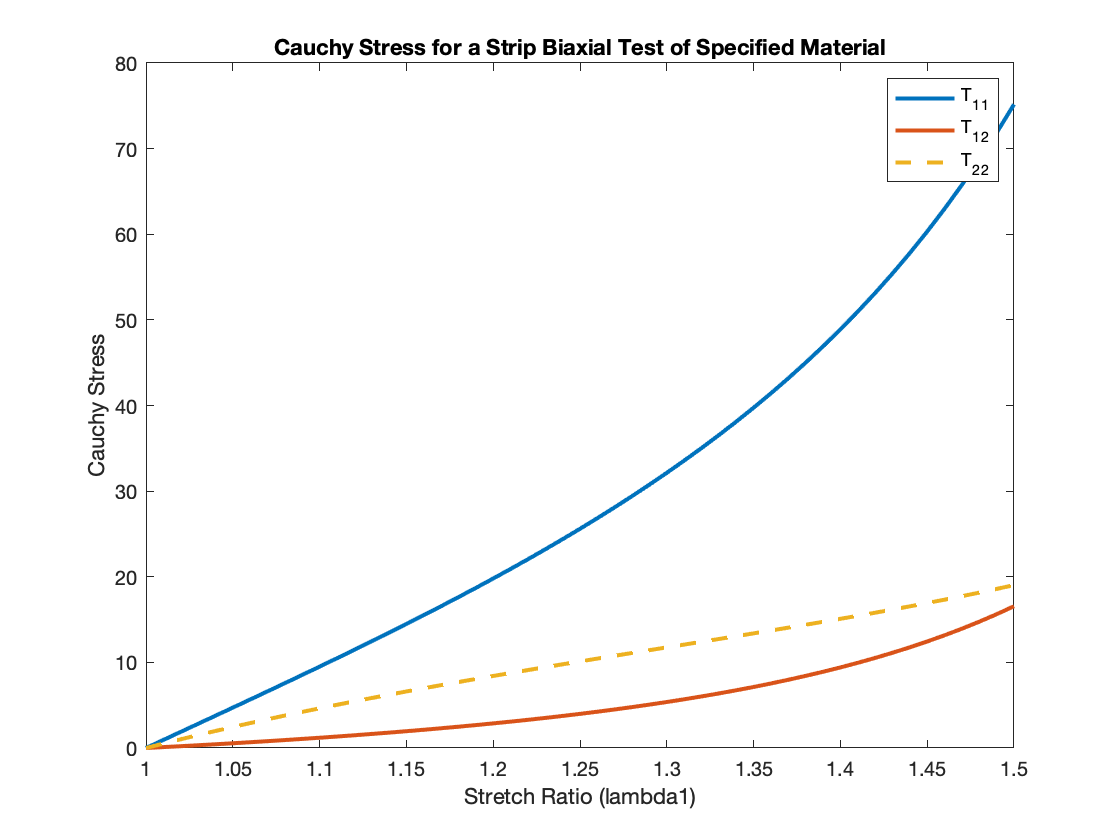


I1 = eval(trace(C));
I4 = eval(lambda_f.^2);

T_11 = subs(T(1,1));
T_12 = subs(T(1,2));
T_22 = subs(T(2,2));

figure(2)
plot(lambda1,T_11,lambda1,T_12,lambda1,T_22, '--', 'linewidth',2)
title(['Cauchy Stress for a Strip Biaxial Test ' ...
    'of Specified Material'])
xlabel('Stretch Ratio (lambda1)')
ylabel('Cauchy Stress')
legend('T_1_1','T_1_2','T_2_2')

## #2

clear all

% PART A

% W = F1(I1,I2)+F2(lambda)
syms C1 C2 C3 C4 C5 C6 I1 I2 lambda1 lambda2 W_lambda lambda lambda_star

F1 = ((C1/2)*(I1-3))+((C2/2)*(I2-3)); % overall equation for finding partial derivatives

W1 = diff(F1,I1)

$$W1 = \frac{C_{1}}{2}$$

W2 = diff(F1,I2)

$$W2 = \frac{C_{2}}{2}$$


W_lambda = piecewise(lambda<1,0,lambda<lambda_star,C3*(exp(C4*(lambda-1))-1),lambda>=lambda_star,(C5*lambda)+C6)

$$W\_lambda = \left\{ \begin{array}{cl} 0 & \text{ if }\lambda <1\\ C_{3}\,\left({\mathrm{e}}^{C_{4}\,\left(\lambda -1\right)}-1\right) & \text{ if }\lambda <\lambda_{\mathrm{star}}\\ C_{6}+C_{5}\,\lambda & \text{ if }\lambda_{\mathrm{star}}\leq \lambda \end{array}\right.$$


% Note that when pulled transverse to fibers, there is no resistance along
%fibers so it behaves isotropic in X1 and use lambda in other directions
F_trans = [lambda1 0 0;
           0 1/sqrt(lambda1) 0;
           0 0 1/sqrt(lambda1)]

$$F\_trans = \left(\begin{array}{ccc} \lambda_{1} & 0 & 0\\ 0 & \frac{1}{\sqrt{\lambda_{1}}} & 0\\ 0 & 0 & \frac{1}{\sqrt{\lambda_{1}}} \end{array}\right)$$


% Note that when pulled along the fibers, all other dimensions will behave
% the same equally and we can assume isotropic in X2
F_fibers = [1/sqrt(lambda2) 0 0;
           0 lambda2 0;
           0 0 1/sqrt(lambda2)]

$$F\_fibers = \left(\begin{array}{ccc} \frac{1}{\sqrt{\lambda_{2}}} & 0 & 0\\ 0 & \lambda_{2} & 0\\ 0 & 0 & \frac{1}{\sqrt{\lambda_{2}}} \end{array}\right)$$


% Use relationship that F*F' = B
B_trans = F_trans*F_trans'

$$B\_trans = \left(\begin{array}{ccc} \lambda_{1}\,\bar{\lambda_{1}} & 0 & 0\\ 0 & \frac{1}{\sqrt{\lambda_{1}}\,\bar{\sqrt{\lambda_{1}}}} & 0\\ 0 & 0 & \frac{1}{\sqrt{\lambda_{1}}\,\bar{\sqrt{\lambda_{1}}}} \end{array}\right)$$

B_fibers = F_fibers*F_fibers'

$$B\_fibers = \left(\begin{array}{ccc} \frac{1}{\sqrt{\lambda_{2}}\,\bar{\sqrt{\lambda_{2}}}} & 0 & 0\\ 0 & \lambda_{2}\,\bar{\lambda_{2}} & 0\\ 0 & 0 & \frac{1}{\sqrt{\lambda_{2}}\,\bar{\sqrt{\lambda_{2}}}} \end{array}\right)$$


%evaluate invariants
I1_trans = eval(trace(B_trans))

$$I1\_trans = \lambda_{1}\,\bar{\lambda_{1}}+\frac{2}{\sqrt{\lambda_{1}}\,\bar{\sqrt{\lambda_{1}}}}$$

I2_trans = eval((1/2)*(trace(B_trans)^2-trace(B_trans^2)))

$$I2\_trans = \frac{{\left(\lambda_{1}\,\bar{\lambda_{1}}+\frac{2}{\sqrt{\lambda_{1}}\,\bar{\sqrt{\lambda_{1}}}}\right)}^{2}}{2}-\frac{{\lambda_{1}}^{2}\,{\bar{\lambda_{1}}}^{2}}{2}-\frac{1}{\lambda_{1}\,{\bar{\sqrt{\lambda_{1}}}}^{2}}$$


I1_fibers = eval(trace(B_fibers))

$$I1\_fibers = \lambda_{2}\,\bar{\lambda_{2}}+\frac{2}{\sqrt{\lambda_{2}}\,\bar{\sqrt{\lambda_{2}}}}$$

I2_fibers = eval((1/2)*(trace(B_fibers)^2-trace(B_fibers^2)))

$$I2\_fibers = \frac{{\left(\lambda_{2}\,\bar{\lambda_{2}}+\frac{2}{\sqrt{\lambda_{2}}\,\bar{\sqrt{\lambda_{2}}}}\right)}^{2}}{2}-\frac{{\lambda_{2}}^{2}\,{\bar{\lambda_{2}}}^{2}}{2}-\frac{1}{\lambda_{2}\,{\bar{\sqrt{\lambda_{2}}}}^{2}}$$



% PART B

% solve equation of W for fibers with given c1-c5 and that lambda* must
% intersect the equation 
% up to lambda* W = ((C1/2)*(I1-3))+((C2/2)*(I2-3))
% at lambda* W = C5* lambda + C6
a = [0;1;0]

a =      0
     1
     0


C_1 = 28.1

C_1 = 28.1000

C_2 = -25.3;
C_3 = 2.5;
C_4 = 31.2;
C_5 = 345.4;
lambda_star = 1.046;

F1 = eval(F1)

$$F1 = \frac{C_{1}\,\left(I_{1}-3\right)}{2}+\frac{C_{2}\,\left(I_{2}-3\right)}{2}$$


C_6 =(C_3*exp((C_4*(lambda_star-1)))-(C_5*lambda_star))

C_6 = -350.7872


% PART C
% solve for cauchy stress
T_trans = 2*(W1 + I1_trans*W2)*(B_trans-W2*B_trans^2) + W_lambda*(a*a');

P_trans = T_trans(3,3);

T_trans = T_trans - P_trans*eye(3)

$$T\_trans = \begin{array}{l} \left(\begin{array}{ccc} \left\{ \begin{array}{cl} \left(\lambda_{1}\,\bar{\lambda_{1}}-\frac{C_{2}\,{\lambda_{1}}^{2}\,{\bar{\lambda_{1}}}^{2}}{2}\right)\,\sigma_{2}-\left(\frac{1}{\sigma_{3}}-\frac{C_{2}}{2\,\lambda_{1}\,{\bar{\sqrt{\lambda_{1}}}}^{2}}\right)\,\sigma_{2} & \text{ if }\left(\lambda \in \mathbb{R}\wedge \lambda_{\mathrm{star}}\in \mathbb{R}\right)\vee \lambda <1 \end{array}\right. & \sigma_{1} & \sigma_{1}\\ \sigma_{1} & \left\{ \begin{array}{cl} 0 & \text{ if }\lambda <1\\ C_{3}\,\left({\mathrm{e}}^{C_{4}\,\left(\lambda -1\right)}-1\right) & \text{ if }\lambda <\lambda_{\mathrm{star}}\\ C_{6}+C_{5}\,\lambda & \text{ if }\lambda_{\mathrm{star}}\leq \lambda \end{array}\right. & \sigma_{1}\\ \sigma_{1} & \sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left\{ \begin{array}{cl} 0 & \text{ if }\left(\lambda \in \mathbb{R}\wedge \lambda_{\mathrm{star}}\in \mathbb{R}\right)\vee \lambda <1 \end{array}\right.\\ \sigma_{2}=C_{1}+C_{2}\,\left(\lambda_{1}\,\bar{\lambda_{1}}+\frac{2}{\sigma_{3}}\right)\\ \sigma_{3}=\sqrt{\lambda_{1}}\,\bar{\sqrt{\lambda_{1}}} \end{array}$$



T_fibers= 2*(W1 + I1_fibers*W2)*(B_fibers-W2*B_fibers^2) + W_lambda*(a*a');

P_fibers = T_fibers(3,3);

T_fibers = T_fibers - P_fibers*eye(3) -

$$T\_fibers = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{2} & \sigma_{2} & \sigma_{2}\\ \sigma_{2} & \left\{ \begin{array}{cl} \sigma_{3}-\sigma_{1} & \text{ if }\lambda <1\\ C_{3}\,\left({\mathrm{e}}^{C_{4}\,\left(\lambda -1\right)}-1\right)-\sigma_{1}+\sigma_{3} & \text{ if }\lambda <\lambda_{\mathrm{star}}\\ C_{6}+C_{5}\,\lambda -\sigma_{1}+\sigma_{3} & \text{ if }\lambda_{\mathrm{star}}\leq \lambda \end{array}\right. & \sigma_{2}\\ \sigma_{2} & \sigma_{2} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(\frac{1}{\sqrt{\lambda_{2}}\,\bar{\sqrt{\lambda_{2}}}}-\frac{C_{2}}{2\,\lambda_{2}\,{\bar{\sqrt{\lambda_{2}}}}^{2}}\right)\,\left(C_{1}+C_{2}\,\left(\lambda_{2}\,\bar{\lambda_{2}}+\frac{2}{\sqrt{\lambda_{2}}\,\bar{\sqrt{\lambda_{2}}}}\right)\right)\\ \sigma_{2}=\left\{ \begin{array}{cl} 0 & \text{ if }\left(\lambda \in \mathbb{R}\wedge \lambda_{\mathrm{star}}\in \mathbb{R}\right)\vee \lambda <1 \end{array}\right.\\ \sigma_{3}=\left(\lambda_{2}\,\bar{\lambda_{2}}-\frac{C_{2}\,{\lambda_{2}}^{2}\,{\bar{\lambda_{2}}}^{2}}{2}\right)\,\left(C_{1}+C_{2}\,\left(\lambda_{2}\,\bar{\lambda_{2}}+\frac{2}{\sqrt{\lambda_{2}}\,\bar{\sqrt{\lambda_{2}}}}\right)\right) \end{array}$$


% PART D

% T from 0 to 1
lambda = 0:0.01:1.2

lambda =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


lambda1 = 0:0.01:1.2

lambda1 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


lambda2 = 0:0.01:1.2

lambda2 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900



Ttrans = eval(T_trans(1,1))

Error using evalin
Check for missing argument or incorrect argument data type in call to function 'in'.

Error in sym/eval (line 14)
s = evalin('caller',vectorize(char(x)));

Tfibers = eval(T_fibers(2,2))

figure(1)
plot(lambda, Ttrans,lambda,Tfibers)
xlabel('Stretch Ratio')
ylabel('Cauchy Stress')
legend('Transverse to Fibers','Along Fibers')
title('Uniaxial Tensil Tests')


% PART E
% the physical interpretation of the C5 is the stiffness of the material as
% it changes with deformation. 